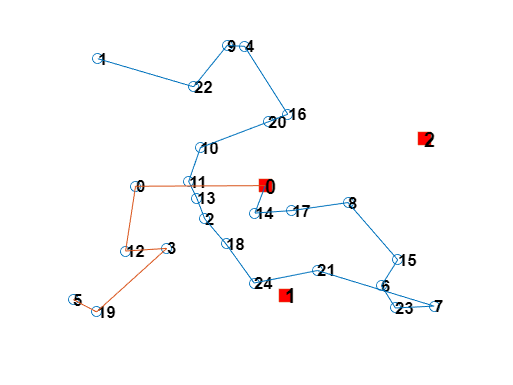

clear;
% Read the CSV file into a table
Customers = readtable('C:\Users\Eppuh\OneDrive - TUNI.fi\Tuni\Kandi\Ohjelma\ant-colony-optimization\customers.csv', 'Delimiter', ';');

% Convert the table columns to numeric vectors
cx = table2array(Customers(:, 1));
cy = table2array(Customers(:, 2));

% Create the scatter plot
scatter(cx, cy);
hold on;

% Read the CSV file into a table
Depots = readtable('C:\Users\Eppuh\OneDrive - TUNI.fi\Tuni\Kandi\Ohjelma\ant-colony-optimization\depots.csv', 'Delimiter', ';');

% Convert the table columns to numeric vectors
dx = table2array(Depots(:, 1));
dy = table2array(Depots(:, 2));

% Create the scatter plot
scatter(dx, dy, 'Marker', 's', 'MarkerFaceColor', 'r', 'SizeData', 100);

% Add text labels for customer indices
for i = 1:length(cx)
    text(cx(i), cy(i), num2str(i - 1), 'Color', 'black', 'FontSize', 10, 'FontWeight', 'bold');
end

% Add text labels for depot indices
for i = 1:length(dx)
    text(dx(i), dy(i), num2str(i - 1), 'Color', 'black', 'FontSize', 12, 'FontWeight', 'bold');
end


% Read the CSV file into a cell array
Routes = readtable('C:\Users\Eppuh\OneDrive - TUNI.fi\Tuni\Kandi\Ohjelma\ant-colony-optimization\routes.csv', 'Delimiter', ';');


% Determine the number of depots and customers from the first row
numRoutes = height(Routes);

% Define the number of different colors you want
numColors = numRoutes;

% Generate a colormap with distinct colors
colors = colormap(lines(numColors));

% Loop through every row
for i = 1:numRoutes
    % Access the i-th row using curly braces {}
    row = Routes{i, :};



    X = [dx(row(1,1) + 1, 1)];
    Y = [dy(row(1,1) + 1, 1)];

    for j = 2:length(row)

        if isnan(row(1,j))
            continue;
        end
        
        X = [X, cx(row(1,j) + 1, 1)];
        Y = [Y, cy(row(1,j) + 1, 1)];
    end
    
   line(X, Y, 'Color', colors(i, :));
    
end

ax = gca;
ax.Visible = 'off';

hold off;

clear;